# Parameterization of Buoyancy-Induced Counter-Gradient Turbulent Scalar Transport in a Thermally Stable Atmospheric Boundary Layer

ZhangKang

## Observational Data

The observational data were  collected from a 325-m meteorological tower in Beijing, which is equipped with eddy-covariance systems at seven levels.

clear;
kappa=0.4;
g=9.8;
hz=10;
rou=1.225;
lv=2.4774*10^6;
cp=1005; 
miu=1.6;
sigma=0.015;
NFFT=18000;
N=30;
z=[8,16,47,80,140,200,280];
lenHeight=length(z);
H=24*60/N;
DataDir=['F:\TurbulenceStatistic\TurbulenceStatistic2MR',num2str(N),'min'];
Dir1=fullfile(DataDir,"*",'2014*.txt');
file=dir(Dir1);
A=string(arrayfun(@(x) x.name,file,'UniformOutput',false));
B=regexp(A,'\d*','match');
Len=length(B);
date=zeros(Len,1);
Level=zeros(Len,1);
for i=1:Len
    date(i)=str2double(B{i,1}{1});
    Level(i)=str2double(B{i,1}{2});
end
[~,Ind]=sort(Level);
date=date(Ind);
Level=Level(Ind);
file1=file(Ind);
[~,Ind]=sort(date);
date=date(Ind);
Level=Level(Ind);
file2=file1(Ind);
[Date,~,ib]=unique(date);
lenDate=length(Date);
opts=detectImportOptions(fullfile(file(1).folder,file(1).name));
uStar=NaN(H,lenHeight,lenDate);
meanU=NaN(H,lenHeight,lenDate);
meanCO2=NaN(H,lenHeight,lenDate);
meanT=NaN(H,lenHeight,lenDate);
meanTS=NaN(H,lenHeight,lenDate);
meanP=NaN(H,lenHeight,lenDate);
tau=NaN(H,lenHeight,lenDate);
sigmaT=NaN(H,lenHeight,lenDate);
wCO2=NaN(H,lenHeight,lenDate);
uw=NaN(H,lenHeight,lenDate);
vw=NaN(H,lenHeight,lenDate);
uv=NaN(H,lenHeight,lenDate);
uCO2=NaN(H,lenHeight,lenDate);
vCO2=NaN(H,lenHeight,lenDate);
uT=NaN(H,lenHeight,lenDate);
vT=NaN(H,lenHeight,lenDate);
wwCO2=NaN(H,lenHeight,lenDate);
deltaS0=NaN(H,lenHeight,lenDate);
M12cw=NaN(H,lenHeight,lenDate);
M21cw=NaN(H,lenHeight,lenDate);
Rcw=NaN(H,lenHeight,lenDate);
M30cw=NaN(H,lenHeight,lenDate);
M03cw=NaN(H,lenHeight,lenDate);
sigmaW=NaN(H,lenHeight,lenDate);
sigmaU=NaN(H,lenHeight,lenDate);
sigmaV=NaN(H,lenHeight,lenDate);
sigmaCO2=NaN(H,lenHeight,lenDate);
wTS=NaN(H,lenHeight,lenDate);
wT=NaN(H,lenHeight,lenDate);
zeta=NaN(H,lenHeight,lenDate);
RTCO2=NaN(H,lenHeight,lenDate);
SteadyState=zeros(H,lenHeight,lenDate);
TKE=NaN(H,lenHeight,lenDate);% TKE
TkeDissip=NaN(H,lenHeight,lenDate);
TCO2=NaN(H,lenHeight,lenDate);
phi=NaN(H,lenHeight,lenDate);
phiU=NaN(H,lenHeight,lenDate);
phiM12cw=NaN(H,lenHeight,lenDate);
phiT=NaN(H,lenHeight,lenDate);
phiT1=phiT;

SteadyStateWT=false(H,lenHeight,lenDate);
%tic
parfor i=1:lenDate
    Ind=find(ib==i);
    Level1=Level(Ind);
    file3=file2(Ind);
    [~,Ind]=sort(Level1);
    file3=file3(Ind);
    len=length(file3);
    uStar_1=uStar(:,:,i);
    meanU_1=meanU(:,:,i);
    meanT_1=meanT(:,:,i);
    meanP_1=meanP(:,:,i);
    meanCO2_1=meanCO2(:,:,i);
    wCO2_1=wCO2(:,:,i);
    uw_1=uw(:,:,i);
    vw_1=vw(:,:,i);
    uv_1=uv(:,:,i);
    uCO2_1=uCO2(:,:,i);
    vCO2_1=vCO2(:,:,i);
    uT_1=uT(:,:,i);
    vT_1=vT(:,:,i);
    wwCO2_1=wwCO2(:,:,i);
    deltaS0_1=deltaS0(:,:,i);
    M12cw_1=M12cw(:,:,i);
    M21cw_1=M21cw(:,:,i);
    Rcw_1=Rcw(:,:,i);
    M03cw_1=M03cw(:,:,i);
    M30cw_1=M30cw(:,:,i);
    sigmaU_1=sigmaU(:,:,i);
    sigmaV_1=sigmaV(:,:,i);
    sigmaW_1=sigmaW(:,:,i);
    sigmaCO2_1=sigmaCO2(:,:,i);
    tau_1=tau(:,:,i);
    sigmaT_1=sigmaT(:,:,i);
    wTS_1=wTS(:,:,i);
    wT_1=wT(:,:,i);
    meanTS_1=meanTS(:,:,i);
    zeta_1=zeta(:,:,i);
    RTCO2_1=RTCO2(:,:,i);
    TCO2_1=TCO2(:,:,i);
    SteadyState_1=SteadyState(:,:,i);
    SteadyStateWT_1=SteadyStateWT(:,:,i);
    TKE_1=TKE(:,:,i);
    TkeDissip_1=TkeDissip(:,:,i);
    z1=[8,16,47,80,140,200,280];
    for j=1:7
        k=find(Level1==z1(j));
        if isempty(k)
            continue;
        end
        filename=fullfile(file3(k).folder,file3(k).name);
        data=readtable(filename, opts);
        uStar_1(:,j)=data.uStar;
        meanU_1(:,j)=data.meanU;
        meanT_1(:,j)=data.meanT;
        meanTS_1(:,j)=data.meanTS;
        meanCO2_1(:,j)=data.meanCO2;
        meanP_1(:,j)=data.meanP;
        wCO2_1(:,j)=data.wCO2Webb;
        uw_1(:,j)=data.uw;
        wwCO2_1(:,j)=data.wwCO2;
        deltaS0_1(:,j)=data.deltaS0;
        M12cw_1(:,j)=data.M12cw;
        M21cw_1(:,j)=data.M21cw;
        Rcw_1(:,j)=data.Rcw;
        M03cw_1(:,j)=data.M03cw;
        M30cw_1(:,j)=data.M30cw;
        sigmaU_1(:,j)=data.sigmaU;
        sigmaV_1(:,j)=data.sigmaV;
        sigmaW_1(:,j)=data.sigmaW;
        sigmaCO2_1(:,j)=data.sigmaCO2;
        tau_1(:,j)=data.tau;
        sigmaT_1(:,j)=data.sigmaT;
        wT_1(:,j)=data.wT;
        wTS_1(:,j)=data.wTS;
        zeta_1(:,j)=data.zeta;
        RTCO2_1(:,j)=data.RTCO2;
        TCO2_1(:,j)=data.TCO2;
        SteadyState_1(:,j)=data.SteadyStateWCO2;
        try
            SteadyStateWT_1(:,j)=data.SteadyStateWT;
        catch
            SteadyStateWT_1(:,j)=0;
        end
        TKE_1(:,j)=data.tke;
        TkeDissip_1(:,j)=data.epsilon;
        vw_1(:,j)=data.vw;
        uv_1(:,j)=data.uv;
        uCO2_1(:,j)=data.uCO2;
        vCO2_1(:,j)=data.vCO2;
        uT_1(:,j)=data.uT;
        vT_1(:,j)=data.vT;

    end
    uStar(:,:,i)=uStar_1;
    meanU(:,:,i)=meanU_1;
    meanT(:,:,i)=meanT_1;
    meanTS(:,:,i)=meanTS_1;
    meanCO2(:,:,i)=meanCO2_1;
    meanP(:,:,i)=meanP_1;
    wCO2(:,:,i)=wCO2_1;
    uw(:,:,i)=uw_1;
    vw(:,:,i)=vw_1;
    uv(:,:,i)=uv_1;
    uCO2(:,:,i)=uCO2_1;
    vCO2(:,:,i)=vCO2_1;
    uT(:,:,i)=uT_1;
    vT(:,:,i)=vT_1;
    wwCO2(:,:,i)=wwCO2_1;
    deltaS0(:,:,i)=deltaS0_1;
    M12cw(:,:,i)=M12cw_1;
    M21cw(:,:,i)=M21cw_1;
    Rcw(:,:,i)=Rcw_1;
    M03cw(:,:,i)=M03cw_1;
    M30cw(:,:,i)=M30cw_1;
    sigmaU(:,:,i)=sigmaU_1;
    sigmaV(:,:,i)=sigmaV_1;
    sigmaW(:,:,i)=sigmaW_1;
    sigmaCO2(:,:,i)=sigmaCO2_1;
    tau(:,:,i)=tau_1;
    sigmaT(:,:,i)=sigmaT_1;
    wTS(:,:,i)=wTS_1;
    wT(:,:,i)=wT_1;
    zeta(:,:,i)=zeta_1;
    RTCO2(:,:,i)=RTCO2_1;
    TCO2(:,:,i)=TCO2_1;
    SteadyState(:,:,i)=SteadyState_1;
    SteadyStateWT(:,:,i)=SteadyStateWT_1;
    TKE(:,:,i)=TKE_1;
    TkeDissip(:,:,i)=TkeDissip_1;
end


### Vertical Gradient of Mean Field

PTheta=temperature_to_potential_temperature(meanT,meanP*1e3)-273.15;
phiT=NaN(H,lenHeight,lenDate);
phiT1=NaN(H,lenHeight,lenDate);
parfor i=1:size(PTheta,3)
    meanTP=PTheta(:,:,i);
    for j=1:H
        ind=~isnan(meanTP(j,:));

        if sum(ind)>4
            [p, s] = spaps(z(ind), meanTP(j,ind), 0.01);
            dp = fnder(p);
            phiTT=fnval(dp,z);
            phiTT(~ind)=nan;
            phiT1(j,:,i)=phiTT;
            coe=polyfit(log(z(ind)),meanTP(j,ind),3);
            coe1=polyder(coe);
            phiTT=polyval(coe1,log(z))./z;
            phiTT(~ind)=nan;
            phiT(j,:,i)=phiTT;
        else
            phiT(j,:,i)=nan;
            phiT1(j,:,i)=nan;
        end
    end
end


筛选光滑的平均风速廓线

phiU1 光滑样条函数拟合

phiU 三次多项式拟合

phiU1=NaN(H,lenHeight,lenDate);
phiU=NaN(H,lenHeight,lenDate);
parfor i=1:length(meanU)
    meanTP=meanU(:,:,i);
    for j=1:H
        ind=~isnan(meanTP(j,:));

        if sum(ind)>4
            [p, s] = spaps(z(ind), meanTP(j,ind), 0.01);
            dp = fnder(p);
            phiTT=fnval(dp,z);
            phiTT(~ind)=nan;
            phiU1(j,:,i)=phiTT;
            coe=polyfit(log(z(ind)),meanTP(j,ind),3);
            coe1=polyder(coe);
            phiTT=polyval(coe1,log(z))./z;
            phiTT(~ind)=nan;
            phiU(j,:,i)=phiTT;
        else
            phiU(j,:,i)=nan;
            phiU1(j,:,i)=nan;
        end
    end
end




筛选 光滑CO2廓线

phiC1=NaN(H,lenHeight,lenDate);
phiC=NaN(H,lenHeight,lenDate);
parfor i=1:size(meanCO2,3)
    meanTP=meanCO2(:,:,i);
    for j=1:H
        ind=~isnan(meanTP(j,:));
        z2=[8,16,47,80,140,200,280];
        if sum(ind)>4
            [p, s] = spaps(z2(ind), meanTP(j,ind), 0.01);
            dp = fnder(p);
            phiTT=fnval(dp,z2);
            phiTT(~ind)=nan;
            phiC1(j,:,i)=phiTT;
            coe=polyfit(log(z2(ind)),meanTP(j,ind),3);
            coe1=polyder(coe);
            phiTT=polyval(coe1,log(z2))./z2;
            phiTT(~ind)=nan;
            phiC(j,:,i)=phiTT;
        else
            phiC(j,:,i)=nan;
            phiC1(j,:,i)=nan;
        end
    end
end

zeta1=zeta;

## Result

zeta=zeta1;
phiT(phiT<0)=nan;
meanWithoutNaN = @(x) median(x(~isnan(x)));
countWithoutNaN = @(x) sum(~isnan(x));
Lag=true(size(phiU));
Ri=phiT./(PTheta+273)./phiU.^2*9.8;

KH=-wTS./phiT;
KM=-sign(uw).*uStar.^2./phiU;
Rif=-(9.8./(PTheta+273)).*wTS./(-sign(uw).*uStar.^2.*phiU);
txz=(KM.*phiU.^2);
AA=uw./uStar.^2;

% KM=uStar.^2./phiU;
KC=-wCO2./phiC;
PrT=KM./KH;
ScT=KM./KC;
Az=sigmaW.^2./(2*TKE);
Lag(KH<0|KM<0|isnan(KH)|isnan(KM)|uStar<0.01|KC<0)=false;
Lag(phiU<0.001|phiU>0.2)=false;
Lag(wTS>-0.0005|wTS<-0.1)=false;
Lag(phiT<0.001|phiC>-0.001)=false;
Lag(sigmaW<1e-2)=false;
Lag(Rif>1|Rif<0)=false;

%Lag(~SteadyStateWT)=false;
Az(~Lag)=nan;
Rif(~Lag)=nan;
PrT(~Lag)=nan;
Ri(~Lag)=nan;
ScT(~Lag)=nan;
zeta(~Lag)=nan;
%ScT(isnan(KC)|KC<0.1|abs(phiC)<0.001)=nan;
KM(~Lag)=nan;
KH(~Lag)=nan;
KC(~Lag)=nan;
%Rif(Rif>0.6|Rif<0)=nan;

###  Figure2

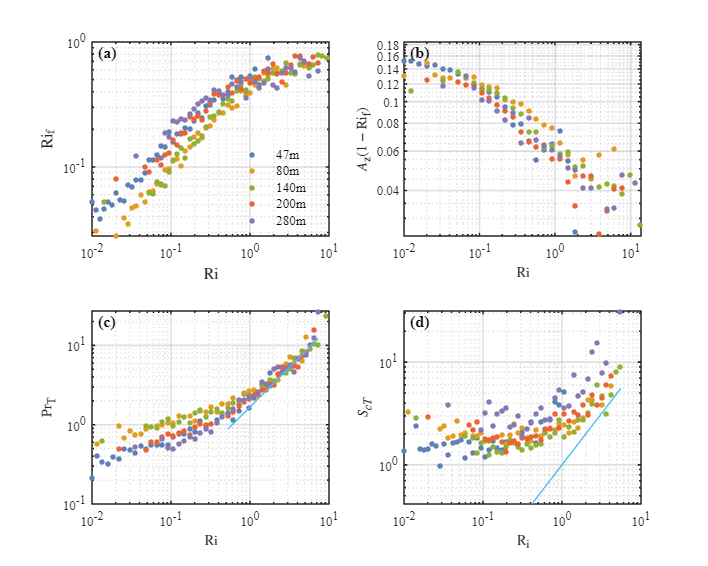

fig = figure('Position', [100 100 1000 800]);
%set(gcf, 'Color', [0.97 0.97 0.97]);

% Define Mathematica-style colors
colors = [
    [0.368417, 0.506779, 0.709798];
    [0.880722, 0.611041, 0.142051];
    [0.560181, 0.691569, 0.194885];
    [0.922526, 0.385626, 0.209179];
    [0.528488, 0.470624, 0.701351]
];

% Plot settings
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultAxesBox', 'on');

% Create subplot
subplot(2,2,1)
for i = 3:7
    Ri6 = reshape(Ri(:,i,:),[],1);
    Rif6 = reshape(Rif(:,i,:),[],1);
    
    [G,E] = discretize(Ri6,[logspace(-2,-0.5,30),logspace(-0.5,2,45)]);
    [a,~] = unique(G(~isnan(G)));
    E = E([a;a(end)+1]);
    [G,E] = discretize(Ri6,E);
    a = splitapply(countWithoutNaN,Rif6,G);
    ind = find(a>0,1,'last');
    
    b = E(ind+1);
    E(find(a<10)+1) = [];
    ind1 = find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1 = [E,b];
        else
            E1 = E;
        end
    end
    
    [G,E] = discretize(Ri6,E1);
    groupmean = splitapply(meanWithoutNaN,Rif6,G);
    
    % Enhanced plotting
    loglog(E(1:end-1), groupmean, '.', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end

% Format axes
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style
lgd = legend('47m','80m','140m','200m','280m', ...
    'Location', 'best', ...
    'FontSize', 10, ...
    'Box', 'off');

% Labels with LaTeX interpreter
xlabel('$\rm Ri$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$\rm Ri_{f}$', 'Interpreter', 'latex', 'FontSize', 12);

% Add annotation

 text(ax.XLim(1)*1.2, ax.YLim(2), '(a)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');

% Export settings
%set(gcf, 'PaperPositionMode', 'auto');

subplot(2,2,2)
R1=Az.*(1-Rif);

for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(R1(:,i,:),[],1);

    
    [G,E]=discretize(Ri6,[logspace(-2,1,30),logspace(1,3,30)]);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    loglog(E(1:end-1), groupmean, '.',  'Color', colors(i-2,:), ...
        'MarkerSize', 12, 'LineWidth', 1.5);
    hold on
end


ylim([0.025 0.185])
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');
text(ax.XLim(1)*1.2, ax.YLim(2), '(b)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');
xlabel('$\rm Ri$','interpreter','latex')
ylabel('$A_{\rm z}(1-\rm Ri_{f})$','interpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,2,3)
PrTR=PrT;

for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    PrT6=reshape(PrTR(:,i,:),[],1);

    [G,E]=discretize(Ri6,[logspace(-2,0,30),logspace(0,3,60)]);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,PrT6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    % E1=[E(unique(G(~isnan(G)))),E(end)];
    % [G,E]=discretize(Ri6,E1);
    % a=splitapply(countWithoutNaN,PrT6,G);
    % E1=[E(find(a>5)+1),E(end)];
    % [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,PrT6,G);
    loglog(E(1:end-1), groupmean, '.', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
loglog((E(14:end-1)),(E(14:end-1)/0.6),'-',"MarkerSize",12);
% 获取第一个子图的位置
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');
% 
% Add legend with enhanced style
% lgd = legend('47m','80m','140m','200m','280m', ...
%     'Location', 'best', ...
%     'FontSize', 10, ...
%     'Box', 'off');
% Add annotation
 text(ax.XLim(1)*1.2, ax.YLim(2), '(c)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');
xlabel('$\rm Ri$','interpreter','latex')
ylabel('$\rm Pr_{T}$','interpreter','latex')
subplot(2,2,4)


for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(ScT(:,i,:),[],1);

    
    [G,E]=discretize(Ri6,[logspace(-2,-0.5,30),logspace(-0.5,3,60)]);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<20)+1)=[];
    ind1=find(a>=20,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=20
            E1=[E,b];

        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    loglog(E(1:end-1), groupmean, '.',  'Color', colors(i-2,:), ...
        'MarkerSize', 12, 'LineWidth', 1.5);
    hold on
end
ax = gca;
loglog((E(14:end-1)),(E(14:end-1)),'-',"MarkerSize",12)
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');
% 获取第二个子图的位置
text(ax.XLim(1)*1.2, ax.YLim(2), '(d)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');
xlabel('$\rm R_i$','interpreter','latex')
ylabel('$S_{cT}$','interpreter','latex')

#### Figure3

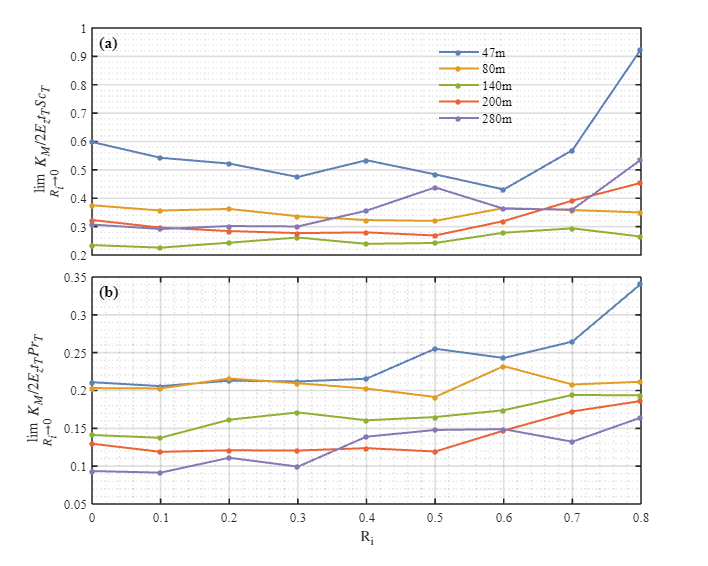

fig = figure('Position', [100 100 1000 800]);
%set(gcf, 'Color', [0.97 0.97 0.97]);

% Define Mathematica-style colors
colors = [
    [0.368417, 0.506779, 0.709798];
    [0.880722, 0.611041, 0.142051];
    [0.560181, 0.691569, 0.194885];
    [0.922526, 0.385626, 0.209179];
    [0.528488, 0.470624, 0.701351]
];

% Plot settings
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultAxesBox', 'on');

clf
subplot(2,1,1)
tau(tau>500)=nan;
% cn=1./(2*phiU.^2.*tau.^2.*Az.*(1-Rif).*[1.5,1.5,1.5,1.5,1.5,1.5,2]);
%cF=KM./(sigmaW.^2.*tau)./PrT;
cF=KM./(sigmaW.^2.*tau)./[0.8,0.8,0.5,0.8,0.9,0.6,0.5];
cF(~Lag)=nan;
cF(cF>2)=nan;
cF(cF<0.05)=nan;
for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(cF(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,0:0.1:10);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<1,2,'last');
    plot(E(1:IndE),groupmean(1:IndE),'.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style
lgd = legend('47m','80m','140m','200m','280m', ...
    'Location', 'best', ...
    'FontSize', 10, ...
    'Box', 'off');
% 获取当前子图的位置
ax1_pos = get(gca, 'Position');
ax1_pos(2)=0.55;
ax1_pos(4)=0.4;
set(gca, 'Position', ax1_pos); 
annotation('textbox', [ax1_pos(1), ax1_pos(2) + ax1_pos(4), 0, 0], ...
    'String', '(a)', 'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold');
%xlabel('$\rm R_i$','interpreter','latex')
xticks([])
ylabel('$\lim _{R_i \rightarrow 0} {K_M} / {2E_z t_T Sc_T}$','interpreter','latex')
subplot(2,1,2)
tau(tau>500)=nan;
% cn=1./(2*phiU.^2.*tau.^2.*Az.*(1-Rif).*[1.5,1.5,1.5,1.5,1.5,1.5,2]);
cn=KM./(sigmaW.^2.*tau)./[1.5,1.5,1.5,1.5,1.5,1.5,1.8];
cn(~Lag)=nan;
% cn(cn>2)=nan;
cn(cn<0.05)=nan;
for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(cn(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,0:0.1:2);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<1,2,'last');
    plot(E(1:IndE),groupmean(1:IndE),'.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style

%legend('47m','80m','140m','200m','280m')
ax2_pos = get(gca, 'Position');
ax2_pos(4)=0.4;
set(gca, 'Position', ax2_pos); 
% 在第二个子图左上角添加编号
annotation('textbox', [ax2_pos(1) , ax2_pos(2) + ax2_pos(4) , 0, 0], ...
    'String', '(b)', 'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('$\rm R_i$','interpreter','latex')
ylabel('$\lim _{R_i \rightarrow 0} {K_M} / {2E_z t_T Pr_T}$','interpreter','latex')

### Figure1

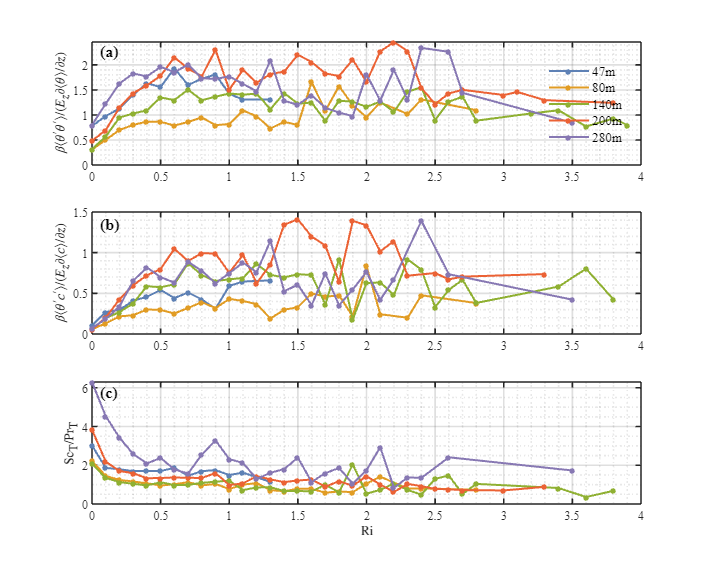

clf
fig = figure('Position', [100 100 1000 800]);
%set(gcf, 'Color', [0.97 0.97 0.97]);

% Define Mathematica-style colors
colors = [
    [0.368417, 0.506779, 0.709798];
    [0.880722, 0.611041, 0.142051];
    [0.560181, 0.691569, 0.194885];
    [0.922526, 0.385626, 0.209179];
    [0.528488, 0.470624, 0.701351]
];

% Plot settings
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultAxesBox', 'on');


subplot(3,1,1)
tau(tau>500)=nan;

R2=sigmaT.^2./sigmaW.^2./phiT*g./(meanT+273);
for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(R2(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,0:0.1:100);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<10,2,'last');
    plot(E(1:end-1), groupmean, '.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
% legend('47m','80m','140m','200m','280m','Location', 'northwest')
% % 获取当前子图的位置
% ax1_pos = get(gca, 'Position');
% set(gca, 'Position', ax1_pos); 
% annotation('textbox', [ax1_pos(1), ax1_pos(2) + ax1_pos(4), 0, 0], ...
%     'String', '(a)', 'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold');
% %xlabel('$\rm R_i$','interpreter','latex')
% %xticks([])
% Format axes
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style
lgd = legend('47m','80m','140m','200m','280m', ...
    'Location', 'best', ...
    'FontSize', 10, ...
    'Box', 'off');

% Labels with LaTeX interpreter
%xlabel('$\rm Ri$', 'Interpreter', 'latex', 'FontSize', 12);


% Add annotation

 text(ax.XLim(1)+0.06, ax.YLim(2)-0.02, '(a)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');


ylabel('$\beta\langle\theta^\prime\theta^\prime\rangle / (E_z\partial\langle \theta\rangle / \partial z)$','Interpreter','latex')
%xticks([])
subplot(3,1,2)
R2=TCO2./sigmaW.^2./phiC*g./(meanT+273);

for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(R2(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,0:0.1:10);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<10,2,'last');
    plot(E(1:end-1), groupmean, '.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style

% Labels with LaTeX interpreter
%xlabel('$\rm Ri$', 'Interpreter', 'latex', 'FontSize', 12);


% Add annotation

 text(ax.XLim(1)+0.06, ax.YLim(2)-0.02, '(b)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');

%xticks([])
ylabel('$\beta\langle\theta^\prime c^\prime\rangle / (E_z\partial\langle c\rangle / \partial z)$','Interpreter','latex')
subplot(3,1,3)
R2=ScT./PrT;

for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(R2(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,0:0.1:10);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<10,2,'last');
    plot(E(1:end-1), groupmean, '.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end
% R1=(ScT);
% R2=PrT;
% for i=3:7
%     Ri6=reshape(Ri(:,i,:),[],1);
%     Rif6=reshape(R1(:,i,:),[],1);
%     R26=reshape(R2(:,i,:),[],1);
% 
%     [G,E]=discretize(Ri6,0:0.1:100);
%     [a,~]=unique(G(~isnan(G)));
%     E=E([a;a(end)+1]);
%     [G,E]=discretize(Ri6,E);
%     a=splitapply(countWithoutNaN,Rif6,G);
%     a2=splitapply(countWithoutNaN,R26,G);
%     ind=find(a>0&a2>0,1,'last');
%     %
%     b=E(ind+1);
%     E(find(a<20|a2<20)+1)=[];
%     ind1=find(a>=20&a2>=20,1,'last');
%     if ind1<ind
%         if sum(a(ind1+1:ind))>=20 && sum(a2(ind1+1:ind))>=20
%             E1=[E,b];
% 
%         else
%             E1=E;
%         end
%     end
%     [G,E]=discretize(Ri6,E1);
%     groupmean=splitapply(meanWithoutNaN,Rif6,G)./splitapply(meanWithoutNaN,R26,G);
%     IndE=find(E<10,2,'last');
%     plot(E(1:end-1), groupmean, '.-', ...
%         'Color', colors(i-2,:), ...
%         'MarkerSize', 12, ...
%         'LineWidth', 1.5);
%     hold on
% end
ax = gca;
set(ax, 'XGrid', 'on', 'YGrid', 'on', ...
    'GridAlpha', 0.15, ...
    'MinorGridAlpha', 0.1, ...
    'XMinorGrid', 'on', ...
    'YMinorGrid', 'on');

% Add legend with enhanced style

% Labels with LaTeX interpreter
%xlabel('$\rm Ri$', 'Interpreter', 'latex', 'FontSize', 12);


% Add annotation

 text(ax.XLim(1)+0.06, ax.YLim(2)-0.02, '(c)', ...
    'FontSize', 12, ...
    'FontWeight', 'bold', ...
    'VerticalAlignment', 'top');

ylabel('$\rm Sc_T/Pr_T$','interpreter','latex')
xlabel('$\rm Ri$','interpreter','latex')

clf
fig = figure('Position', [100 100 1000 800]);
%set(gcf, 'Color', [0.97 0.97 0.97]);

% Define Mathematica-style colors
colors = [
    [0.368417, 0.506779, 0.709798];
    [0.880722, 0.611041, 0.142051];
    [0.560181, 0.691569, 0.194885];
    [0.922526, 0.385626, 0.209179];
    [0.528488, 0.470624, 0.701351]
];

% Plot settings
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');
set(groot, 'defaultAxesLineWidth', 1.2);
set(groot, 'defaultAxesBox', 'on');



tau(tau>500)=nan;

R2=(PrT)./Ri.*(1-Rif).*Az;
for i=3:7
    Ri6=reshape(Ri(:,i,:),[],1);
    Rif6=reshape(R2(:,i,:),[],1);
    Rif6(Rif6<0)=nan;

    [G,E]=discretize(Ri6,[logspace(-2,0,30),logspace(0,3,60)]);
    [a,~]=unique(G(~isnan(G)));
    E=E([a;a(end)+1]);
    [G,E]=discretize(Ri6,E);
    a=splitapply(countWithoutNaN,Rif6,G);
    ind=find(a>0,1,'last');
    %
    b=E(ind+1);
    E(find(a<10)+1)=[];
    ind1=find(a>=10,1,'last');
    if ind1<ind
        if sum(a(ind1+1:ind))>=10
            E1=[E,b];
        else
            E1=E;
        end
    end
    [G,E]=discretize(Ri6,E1);
    groupmean=splitapply(meanWithoutNaN,Rif6,G);
    IndE=find(E<10,2,'last');
    loglog(E(1:end-1), groupmean, '.-', ...
        'Color', colors(i-2,:), ...
        'MarkerSize', 12, ...
        'LineWidth', 1.5);
    hold on
end